% Initilaizing new output variables to some constant values
% Variables initialized are x, theta_1 and theta_2
% The system has the first derivatives of the all values
% All of them are state variables and contribute to y0 which can be defined
% as below
y0 = [1; 0; 2; 0; 3; 0]

y0 =      1
     0
     2
     0
     3
     0


%defining the timespan and sampling rate for the graph
timespan = 0:0.01:8000; 
%using ode45 function (In-built Matlab function) for definining a differential eqn
[t1,y1] = ode45(@twoload,timespan,y0); 
%plotting the above function as a function of time on a graph
disp("The graph is plotted below :")

The graph is plotted below :


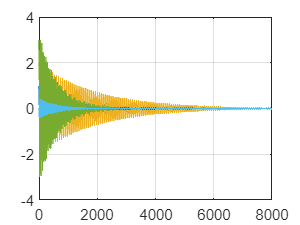

plot(t1,y1)
grid on

function ydot = twoload(t1,y)
M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;
A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];
R=0.01;
[K_Gain_matrix, Pos_def_matrix, Poles] = lqr(A,B,Q,R);
F=-K_Gain_matrix*y;
ydot=zeros(6,1);
% y(1)=x from state space representation          
ydot(1) = y(2); 
%y(2)=xdot from state space representation   
ydot(2)=(F-(g/2)*(m1*sind(2*y(3))+m2*sind(2*y(5)))-(m1*l1*(y(4)^2)*sind(y(3)))-(m2*l2*(y(6)^2)*sind(y(5))))/(M+m1*((sind(y(3)))^2)+m2*((sind(y(5)))^2));%X_DD
%y(3)=theta1 from state space representation   
ydot(3)= y(4);
%y(4)=theta1dot from state space representation   
ydot(4)= (ydot(2)*cosd(y(3))-g*(sind(y(3))))/l1'; %theta1_Ddot;
%y(5)=theta2 from state space representation   
ydot(5)= y(6); %theta 2D
%y(6)=theta2dot from state space representation   
ydot(6)= (ydot(2)*cosd(y(5))-g*(sind(y(5))))/l2; %theta2_Ddot;
end